addpath(genpath('/Users/jiajunhan/Desktop/2022summer/MarkovESValuation-master'));
locations = convertStringsToChars(["NYC","LONGIL","NORTH","WEST"]);

numFiles = 4;
currentFile = cell(numFiles,1);

% % load DAP_1h
for n = 1:numFiles
    location = locations{n};
%     fprintf(currentFile)
    currentFile{n} = readmatrix(strcat('DAP_',location,'_2019_2021.csv'),Delimiter = ',',Range='C:C');
    currentFile{n} = reshape(currentFile{n}(2:end,:),24,numel(currentFile{n}(2:end,:))./24)';
    eval([sprintf('DAP_%s_2019_2021',location),'= currentFile{n}']);
end

% % load RTP_5m
for n = 1:numFiles
    location = locations{n};
%     fprintf(currentFile)
    currentFile{n} = readmatrix(strcat('RTP_',location,'_2019_2021.csv'),Delimiter = ',',Range='C:C');
    currentFile{n} = reshape(currentFile{n}(2:end,:),288,numel(currentFile{n}(2:end,:))./288)';
    eval([sprintf('RTP_%s_2019_2021',location),'= currentFile{n}']);
end

% convert the above to RTP_1h
RTP_5m = cat(1,RTP_LONGIL_2019_2021,RTP_NORTH_2019_2021,RTP_WEST_2019_2021,RTP_NYC_2019_2021);
RTP_1h=zeros(1,24);
for i=1:1:1096*4
    RTP_1h(i,:)= mean(reshape(RTP_5m(i,:),12,24),1);
end

RTP_LONGIL_2019_2021_1h = RTP_1h(1:1096,:);
RTP_NORTH_2019_2021_1h = RTP_1h(1097:1096*2,:);
RTP_WEST_2019_2021_1h = RTP_1h(1096*2+1:1096*3,:);
RTP_NYC_2019_2021_1h = RTP_1h(1096*3+1:1096*4,:);

ZONE = 'NORTH';
eval(['RTP', '= RTP_',ZONE,'_2019_2021_1h''']);
eval(['DAP', '= DAP_',ZONE,'_2019_2021''']);

% 
Ts = 1; % time step
Tp = 24/Ts; % number of timepoint
DD = 365;

lastDay = datetime(2019,12,31);
lambda_RT = reshape(RTP(:,1:DD+1),numel(RTP(:,1:DD+1)),1); % converted to a column vector
lambda_DA = reshape(DAP(:,1:DD+1),numel(DAP(:,1:DD+1)),1); 
lambda_spread = lambda_DA - lambda_RT;
T = numel(lambda_RT); % number of time steps
N = 22; % number of states
G = 10; % state gap

RTP = RTP(:,1:DD); % 1st year's real time price
DAP = DAP(:,1:DD);

close all
plot(lambda_spread(1:240));
hold on
plot(lambda_DA(1:240))
hold on 
plot(lambda_RT(1:240))
hold off
legend('spread','DA','RT')

close all
plot(lambda_spread(1:8760));
hold on
plot(lambda_DA(1:8760))
hold on 
plot(lambda_RT(1:8760))
hold off
legend('spread','DA','RT')

mean(lambda_spread(lambda_spread<0))
% a = lambda_spread .* (lambda_spread<0)
% nonzeros(a)

% %% 90% efficiency
% close all
% j = 10;
% t = tiledlayout(3,3);
% for i=j:8+j
%     nexttile
%     plot(v_da(:,i));
% end

% close all
% plot(v_da(:,23));
% load('v_da_100.mat','v_da');
% % (v_da .* v_da<0)
% ceil(find(v_da<0)/1001)

## 90% efficiency value function

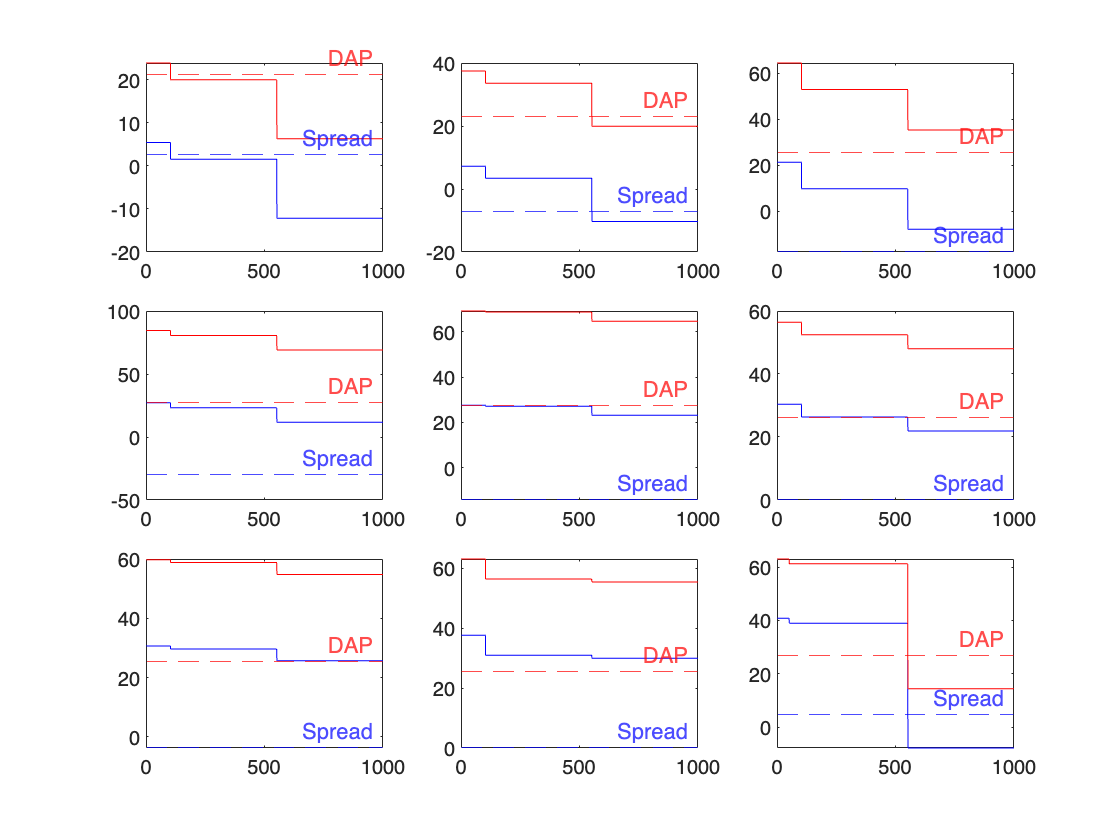

load('v_da_90.mat','v_da');
close all
j = 133;
t = tiledlayout(3,3);
for i=j:8+j
    nexttile
    plot(v_da(:,i),'Color','blue');
    hold on
    plot(v_da(:,i)+lambda_RT(i),'Color','red');
    hold on
    yline(lambda_DA(i),'--','DAP','Color','red');
    hold on 
    yline(lambda_spread(i),'--','Spread','Color','blue');  
    hold off
end

## 100% efficiency value function

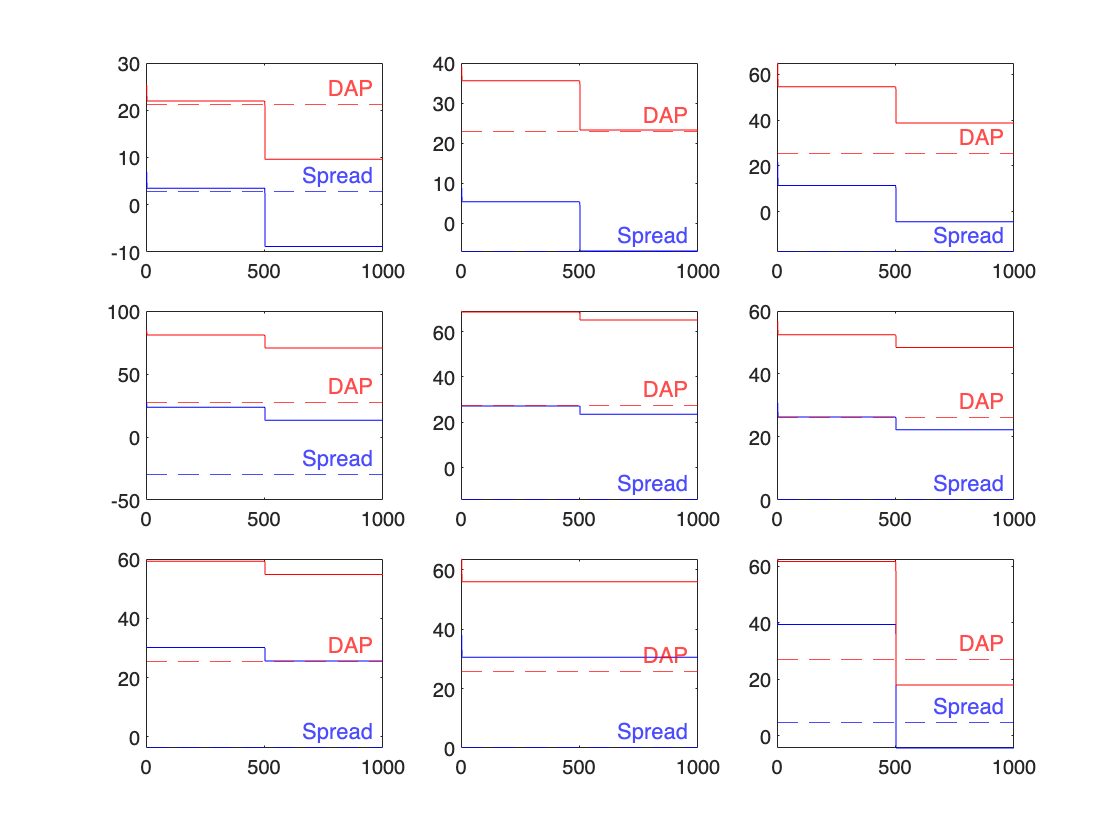

load('v_da_100.mat','v_da');
close all
j = 133;
t = tiledlayout(3,3);
for i=j:8+j
    nexttile
    plot(v_da(:,i),'Color','blue');
    hold on
    plot(v_da(:,i)+lambda_RT(i),'Color','red');
    hold on
    yline(lambda_DA(i),'--','DAP','Color','red');
    hold on 
    yline(lambda_spread(i),'--','Spread','Color','blue');  
    hold off
end

ans =    133
   133
   133
   133
   133
   133
   133
   133
   133
   133


a =     -1    -2
     3     4


ans =      1
     2
